# Class 5 Problem 1 Derivative Pricing KO

## Problem

Calculate the value of call option on KO or PEP using the following numerical methods:

- Black-Scholes

- Random Walks

- Trees

- PDE

### 0. Download Option Prices for KO

At 10:44am KO's [price](https://ca.finance.yahoo.com/quote/KO/options?date=1702598400&p=KO&straddle=false) was given as $53.40. A snap of the call option chain is below. 

We will focus on the $55 dollar level for the exercise.

The implied volatility for the $55 strike call was 18.3% and for the $55 strike put was 22.0%.

C_MKT = 1.03;
P_MKT = 2.62;

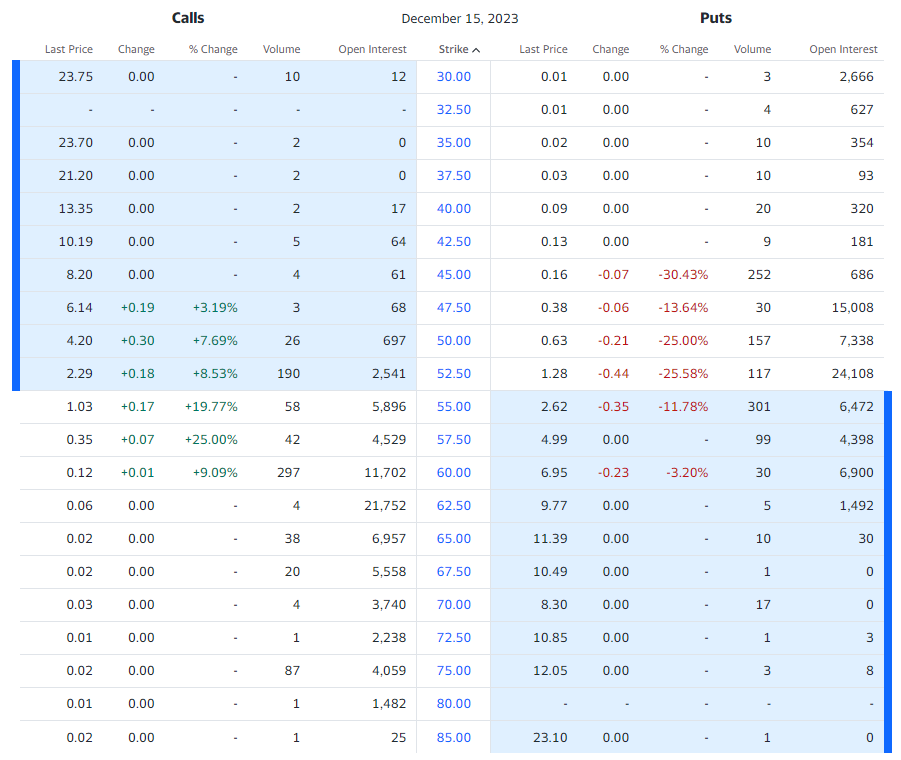

Their dividend data is as follows:

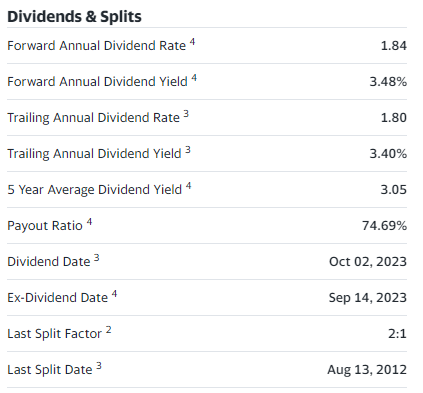

% Download data for Coke
startDate = '2018-10-16';
endDate = '2024-10-13';
KO_data = py.yfinance.download('KO', pyargs('start', startDate, 'end', endDate, 'interval', '1d'));


[*********************100%***********************]  1 of 1 completed


TTKO = table(KO_data);
TTKO = TTKO(1:1257, :);
TTKO = renamevars(TTKO, ["Adj Close"], ["Price"]);
TTKO = removevars(TTKO,["Open","High","Low","Close","Volume"])

TTKO = 1257×2 table
       Date        Price 
    ___________    ______

    16-Oct-2018     37.75
    17-Oct-2018    38.057
    18-Oct-2018     37.85
    19-Oct-2018    38.447
    22-Oct-2018    38.148
    23-Oct-2018    38.472
    24-Oct-2018    38.779
    25-Oct-2018    38.597
    26-Oct-2018    38.107
    29-Oct-2018    38.555
    30-Oct-2018    39.526
    31-Oct-2018    39.733
    01-Nov-2018    39.617
    02-Nov-2018    39.833
    05-Nov-2018    40.406
    06-Nov-2018    40.754


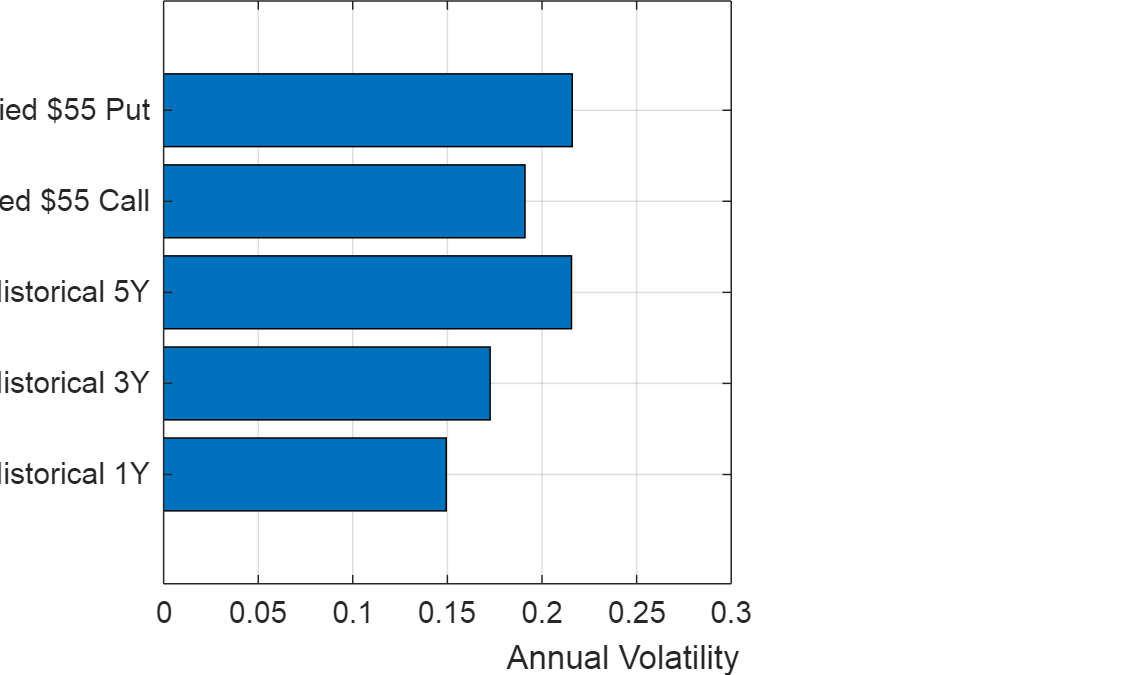

% What is the historical volatility of the stock over different time frames
tHistorical = datenum(TTKO.Date);
SHistorical = TTKO.Price;
rKO = diff(SHistorical) ./ SHistorical(1:end-1);
 
sigmaHist1YEAR = std(rKO(end-252+1:end)) * sqrt(252);
sigmaHist3YEAR = std(rKO(end-2*252+1:end)) * sqrt(252);
sigmaHist5YEAR = std(rKO(1:end)) * sqrt(252);
 
sigma55Call = 0.191; % from the option chain in Yahoo! 20.6
sigma55Put = 0.216; % from the option chain in Yahoo!
 
% Results and Output
figure()
set(gcf,'Position',[0,0,500,300])
 
barh([sigmaHist1YEAR, sigmaHist3YEAR, sigmaHist5YEAR, sigma55Call, sigma55Put])
 
xlabel('Annual Volatility')
set(gca,'YTickLabels', {'Historical 1Y', ...
                        'Historical 3Y', ...
                        'Historical 5Y',... 
                        'Implied $55 Call', ...
                        'Implied $55 Put'})
xlim([0 0.3])
box on
grid on

### 1. Black-Scholes-Merton Model

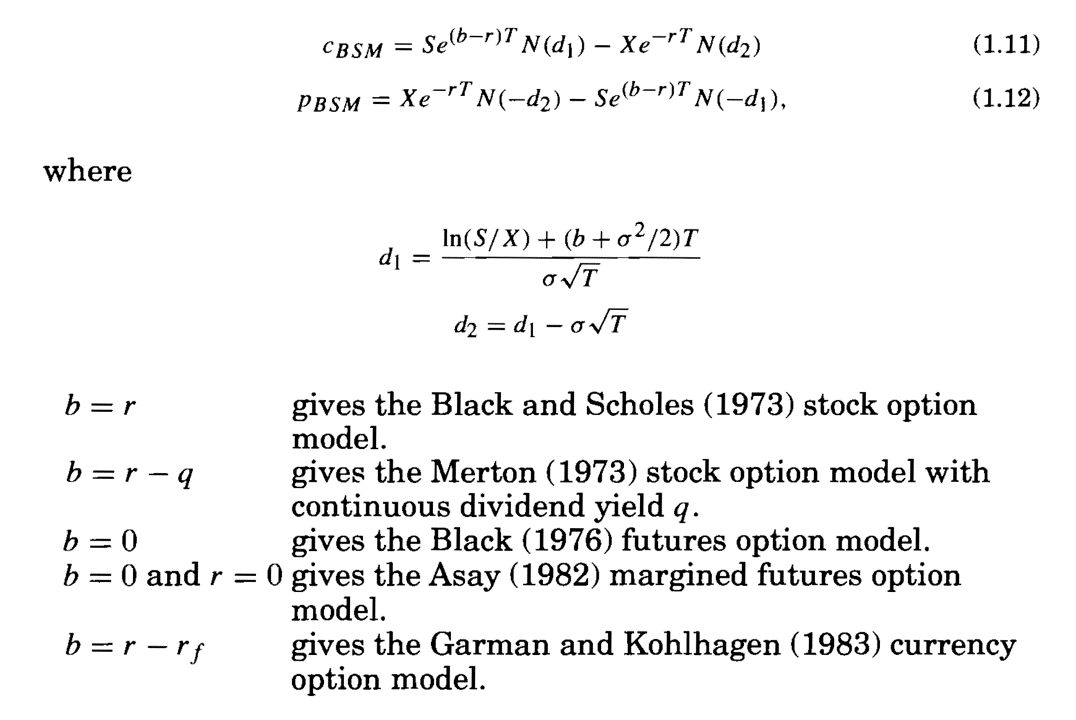

% Basic Market Observations
 
So = SHistorical(end); %53.40; % Current stock price
K = 55; % Strike price for example
r = 0.0531; % SOFR rate of 5.31%
%sigma = 0.1920; % 19.2% from the option chain on Yahoo!
q = 0.018; % trailing annual dividend yield
 
% Prepping the Calculation
 
% For December 15, 2002 we calculate T in years
To = datenum(2023,10,16);
TExpiration = datenum(2023,12,15);
TDays = (TExpiration - To); % in days
T = (TExpiration - To) / 365; % in years
 
% The "known" part
b = r - q;
 
% Calculate Black Scholes price for the option
d1 = (log(So/K) + (b + sigma55Call^2 / 2)*T) / (sigma55Call*sqrt(T));
d2 = d1 - sigma55Call * sqrt(T);
 
C_BSM = So * exp((b-r)*T) * normcdf(d1) - K * exp(-r*T) * normcdf(d2)

C_BSM = 0.4709

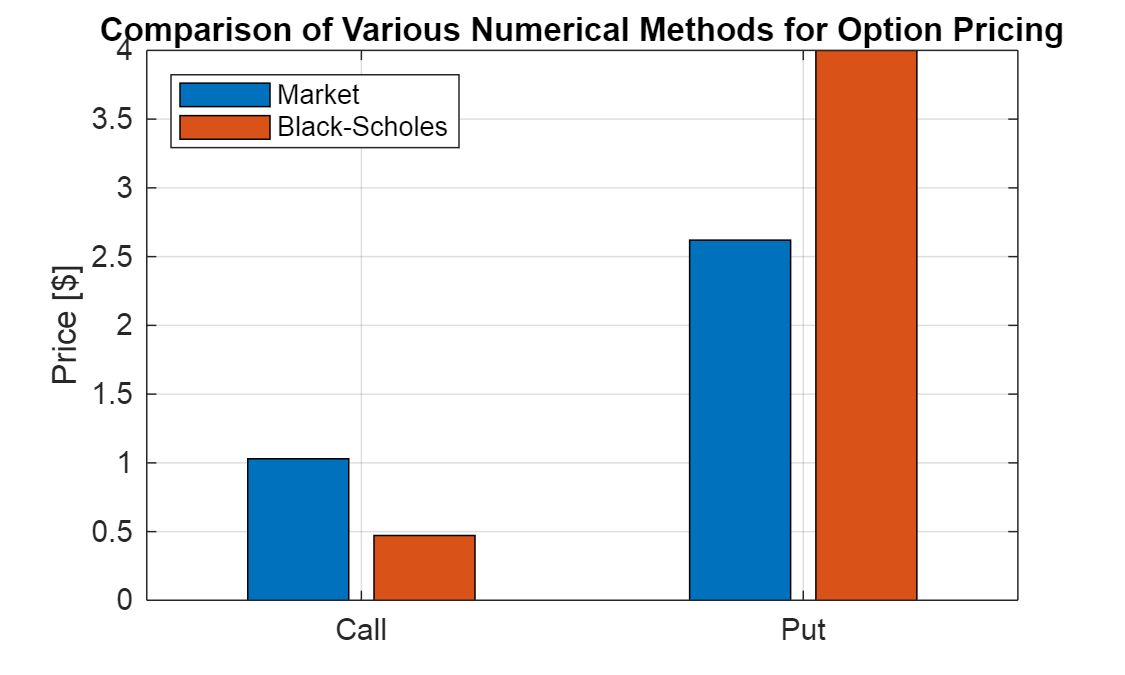

d1 = (log(So/K) + (b + sigma55Put^2 / 2)*T) / (sigma55Put*sqrt(T));
d2 = d1 - sigma55Put * sqrt(T);
 
P_BSM = K * exp(-r*T) * normcdf(-d2) - So * exp((b-r)*T) * normcdf(-d1);
 
% Results and Output
figure()
set(gcf,'Position',[0,0,500,300])
 
bar([C_MKT, C_BSM; P_MKT ,P_BSM])
title('Comparison of Various Numerical Methods for Option Pricing')
ylabel('Price [$]')
legend({'Market','Black-Scholes'}, 'location', 'northwest')
 
%xlabel('Annual Volatility')
set(gca,'XTickLabels', {'Call','Put'})
box on
grid on

### 2. Random Walk

Now we'll calculate the same values for the call option using the random walk model we've already developed.

% Define Extent of Walk and Number of Repititions
NTrials = 1000;
NSteps = TDays;
 
% Generate Normal Random Numbers
U = rand(NSteps, NTrials);
Z = norminv(U);
 
% Estimate RW Param
sigmaRwDays = sigma55Call / sqrt(365);
bRwDays = b / 365; % risk-neutral drift including dividend yield
dt = 1; % for 60 days
 
% The Geometric Random Walk ... we only need the last point for a European option, so this is just for continuity ... 
S_RW = So * cumprod(1 + bRwDays * dt + sigmaRwDays * sqrt(dt) * Z);
 
% For those of you who can't talk matrix yet :-)
% S_RW = zeros(size(U));
% S_RW(1,:) = So;
% for i = 2:NSteps
%     S_RW(i,:) = S_RW(i-1,:) .* (1 + (bRwDays/365) * dt + sigmaRwDays * Z(i,:) * sqrt(dt));
% end% for i
 
% Calculate value of the Call option
C_RW_Expiration = max(S_RW(end,:)-55,0);
PriceExp = 0:1:10;
CountExp = hist(C_RW_Expiration, PriceExp);
ProbExp = CountExp / NTrials;
 
C_RW = PriceExp * ProbExp' % expected value of the option price

C_RW = 0.4420

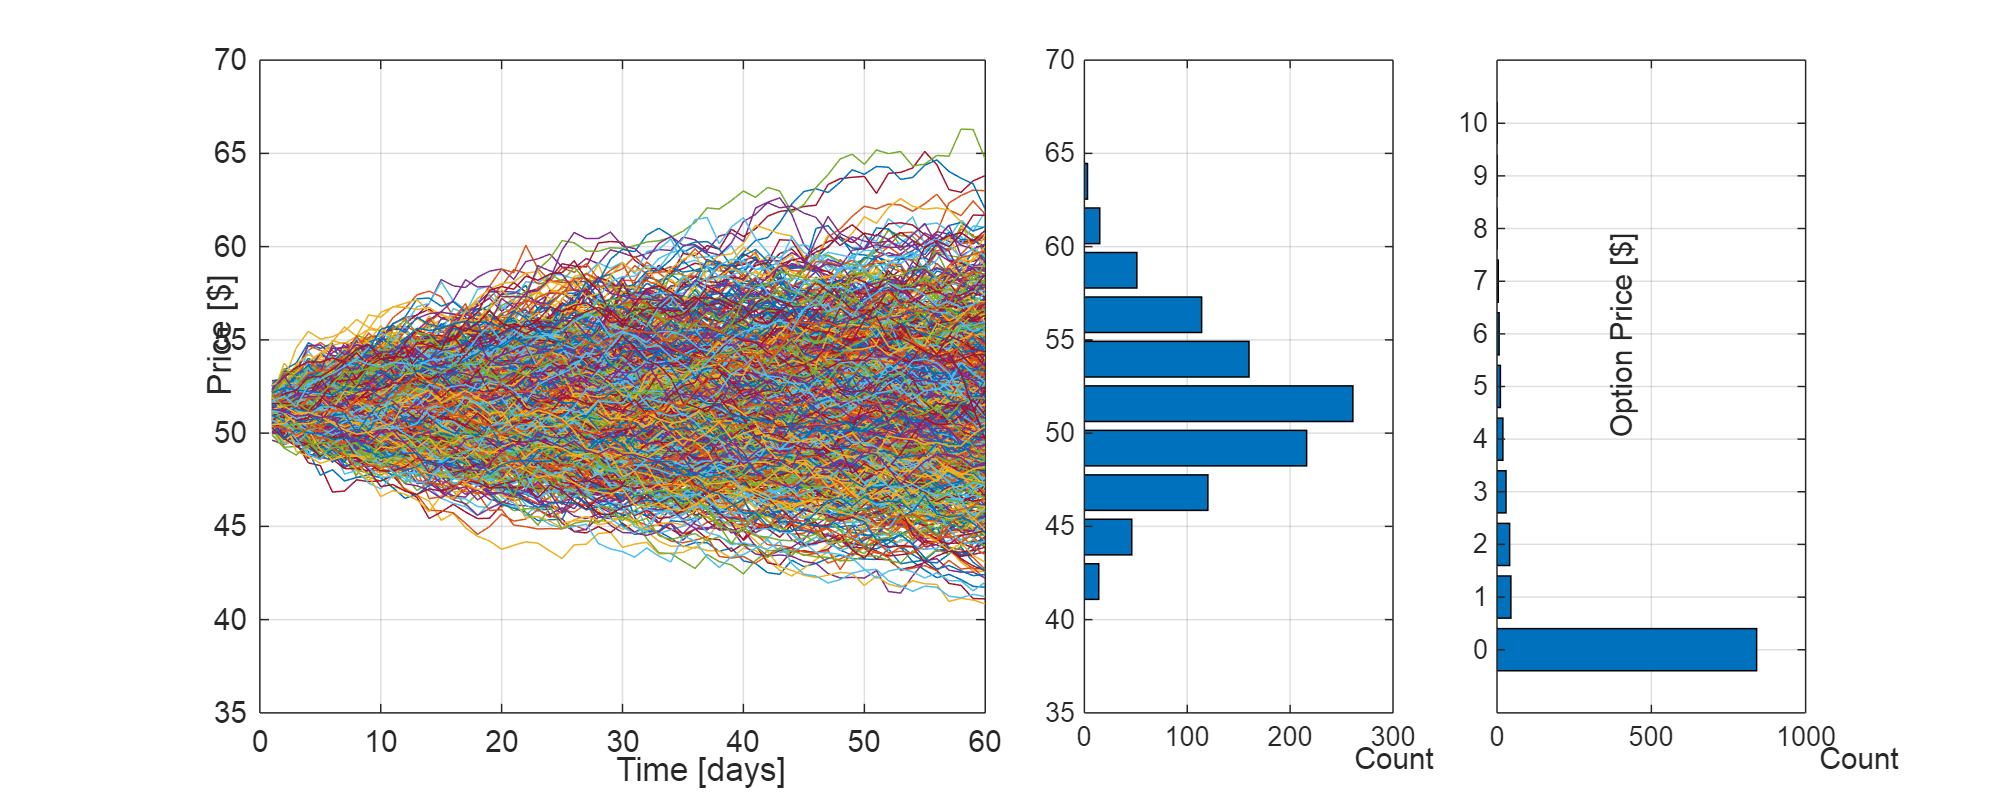


% Results and Graphs
figure()
set(gcf, 'Position', [0 0 1000 400])
 
% Graph the random walks
subplot(1,4,[1,2])
plot(S_RW)
title('Risk Neutral KO Price ... Random Walks')
xlabel('Time [days]')
ylabel('Price [$]')
ylim([35,70])
grid on
 
% Graph KO price at expiration
subplot(1,4,3)
 
[fBin,SBin] = hist(S_RW(end,:),10);
 
barh(SBin, fBin)
ylim([35,70])
grid on
title('Risk Neutral Stock Price')
xlabel('Count')
 
% Graph option price at expiration
subplot(1,4,4)
 
 
barh(PriceExp, CountExp)
title('Risk Neutral Option Price')
grid on
xlabel('Count')
ylabel('Option Price [$]')

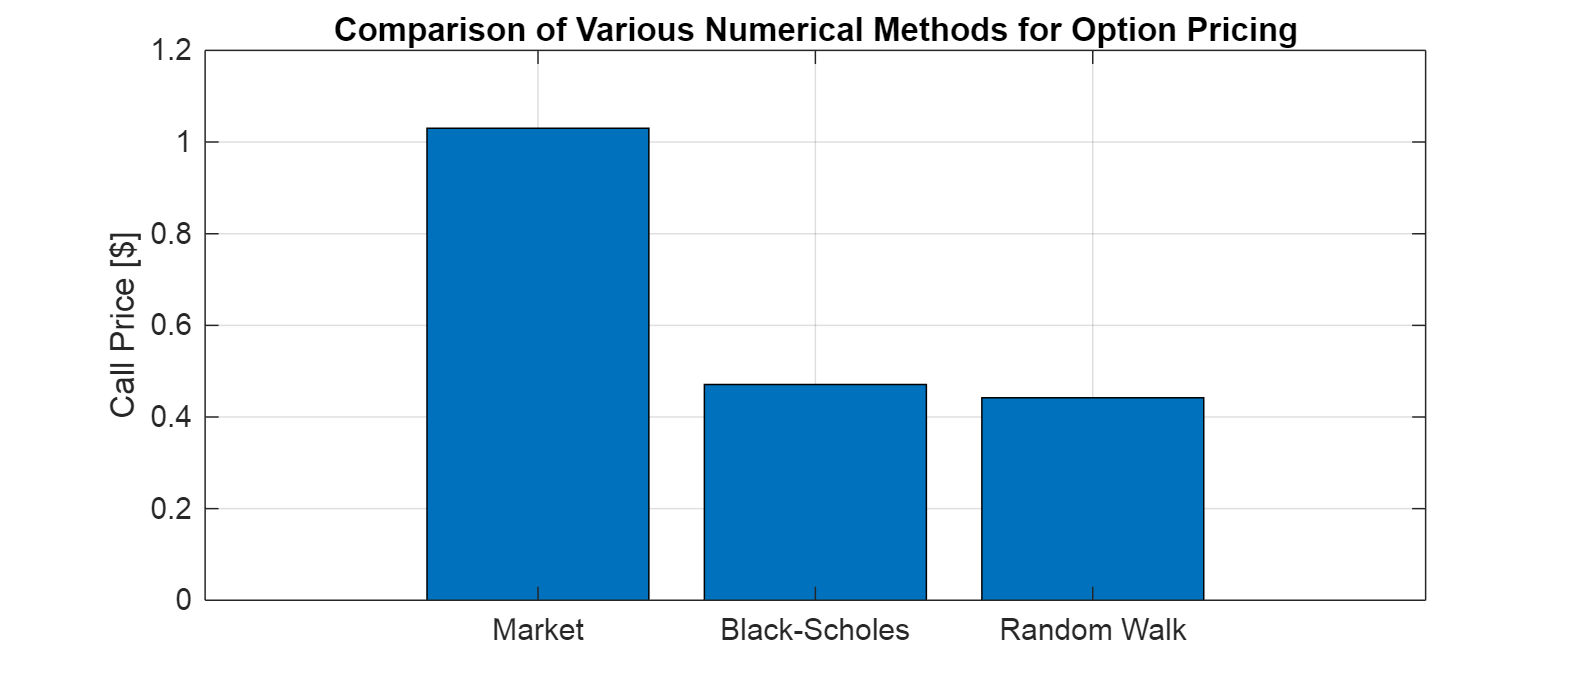


% Update on call option price by various methods
figure()
set(gcf,'Position',[0,0,700,300])
 
bar([C_MKT, C_BSM, C_RW])
title('Comparison of Various Numerical Methods for Option Pricing')
ylabel('Call Price [$]')
set(gca, 'XTickLabels', {'Market','Black-Scholes','Random Walk'})
 
box on
grid on

### 3. Trinomial Trees - Grid Method

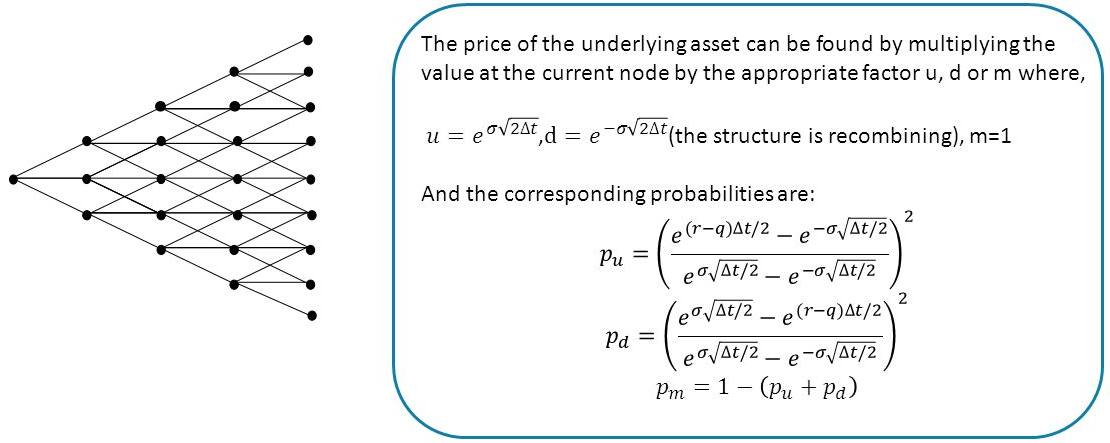

% Parameters for the Trinomial Tree
 
u = exp(sigmaRwDays*sqrt(2*dt));
d = exp(-sigmaRwDays*sqrt(2*dt));
m = 1;
 
numUp = exp(bRwDays * dt/2) - exp(-sigmaRwDays * sqrt(dt/2));
numDn = exp(sigmaRwDays * sqrt(dt/2)) - exp(bRwDays * dt/2);
den = exp(sigmaRwDays * sqrt(dt/2)) - exp(-sigmaRwDays * sqrt(dt/2));
 
pu = (numUp/den)^2;
pd = (-numDn/den)^2;
pm = 1 - (pu + pd);
 
 
% The Stock Tree on the Grid
TriGridHeight = 2 * NSteps - 1;
TriGridWidth = NSteps;
 
STriGrid = NaN(TriGridHeight, TriGridWidth);
 
TAxis = 1:NSteps;
SAxis = zeros(TriGridHeight,1);
 
for i = 1:TriGridHeight
    
    if i < TriGridHeight / 2
       SAxis(i) = So * d ^ (floor(TriGridHeight / 2) - i + 1);
    elseif i > TriGridHeight / 2 + 1
       SAxis(i) = So * u ^ (i - ceil(TriGridHeight / 2));
    elseif i == NSteps
       SAxis(i) = So;
    end%if
 
end%for i
 
 
% Fill in the Trinomial Tree in the grid
for j = 1:NSteps
 
    IBeg = NSteps - j + 1;
    IEnd = NSteps + j - 1;
    I = IBeg:IEnd;
 
    STriGrid(I,j) = SAxis(I);
 
end%for i
 
 
%%% Core Routine Starts here
 
% Determine the option Value ... bit more detailed here
VIntrinsic = max(STriGrid - 55, 0);
VEuro = NaN(size(STriGrid));
VAmer = NaN(size(STriGrid));
 
% Backward Induction
for j = NSteps:-1:1
 
    IBeg = NSteps - j + 1;
    IEnd = NSteps + j - 1;
    I = IBeg:IEnd;
 
    for i = 1:length(I)
 
        IntrinsicValue = VIntrinsic(I(i),j);
 
        if j == NSteps
    
            % Option prices at maturity are just Intrinsic Values
            VEuro(I(i), j) = IntrinsicValue;
            VAmer(I(i), j) = IntrinsicValue;
 
        else
 
            % The Backward Induction Algorithm
 
            VEuro(I(i), j) = exp(-bRwDays*dt) * (pu * VEuro(I(i)+1, j+1) + ...
                                                 pm * VEuro(I(i),   j+1) + ...
                                                 pd * VEuro(I(i)-1, j+1) );
 
            VAmer(I(i), j) = max(IntrinsicValue, exp(-bRwDays*dt) * (pu * VAmer(I(i)+1, j+1) + ...
                                                                     pm * VAmer(I(i),   j+1) + ...
                                                                     pd * VAmer(I(i)-1, j+1) ) );
        end%if
 
    end%for i
 
end%for j
 
VIntrinsic(NSteps,1)

ans = 0


C_TRI_EURO = VEuro(NSteps,1)

C_TRI_EURO = 0.4599

C_TRI_AMER = VAmer(NSteps,1)

C_TRI_AMER = 0.4599

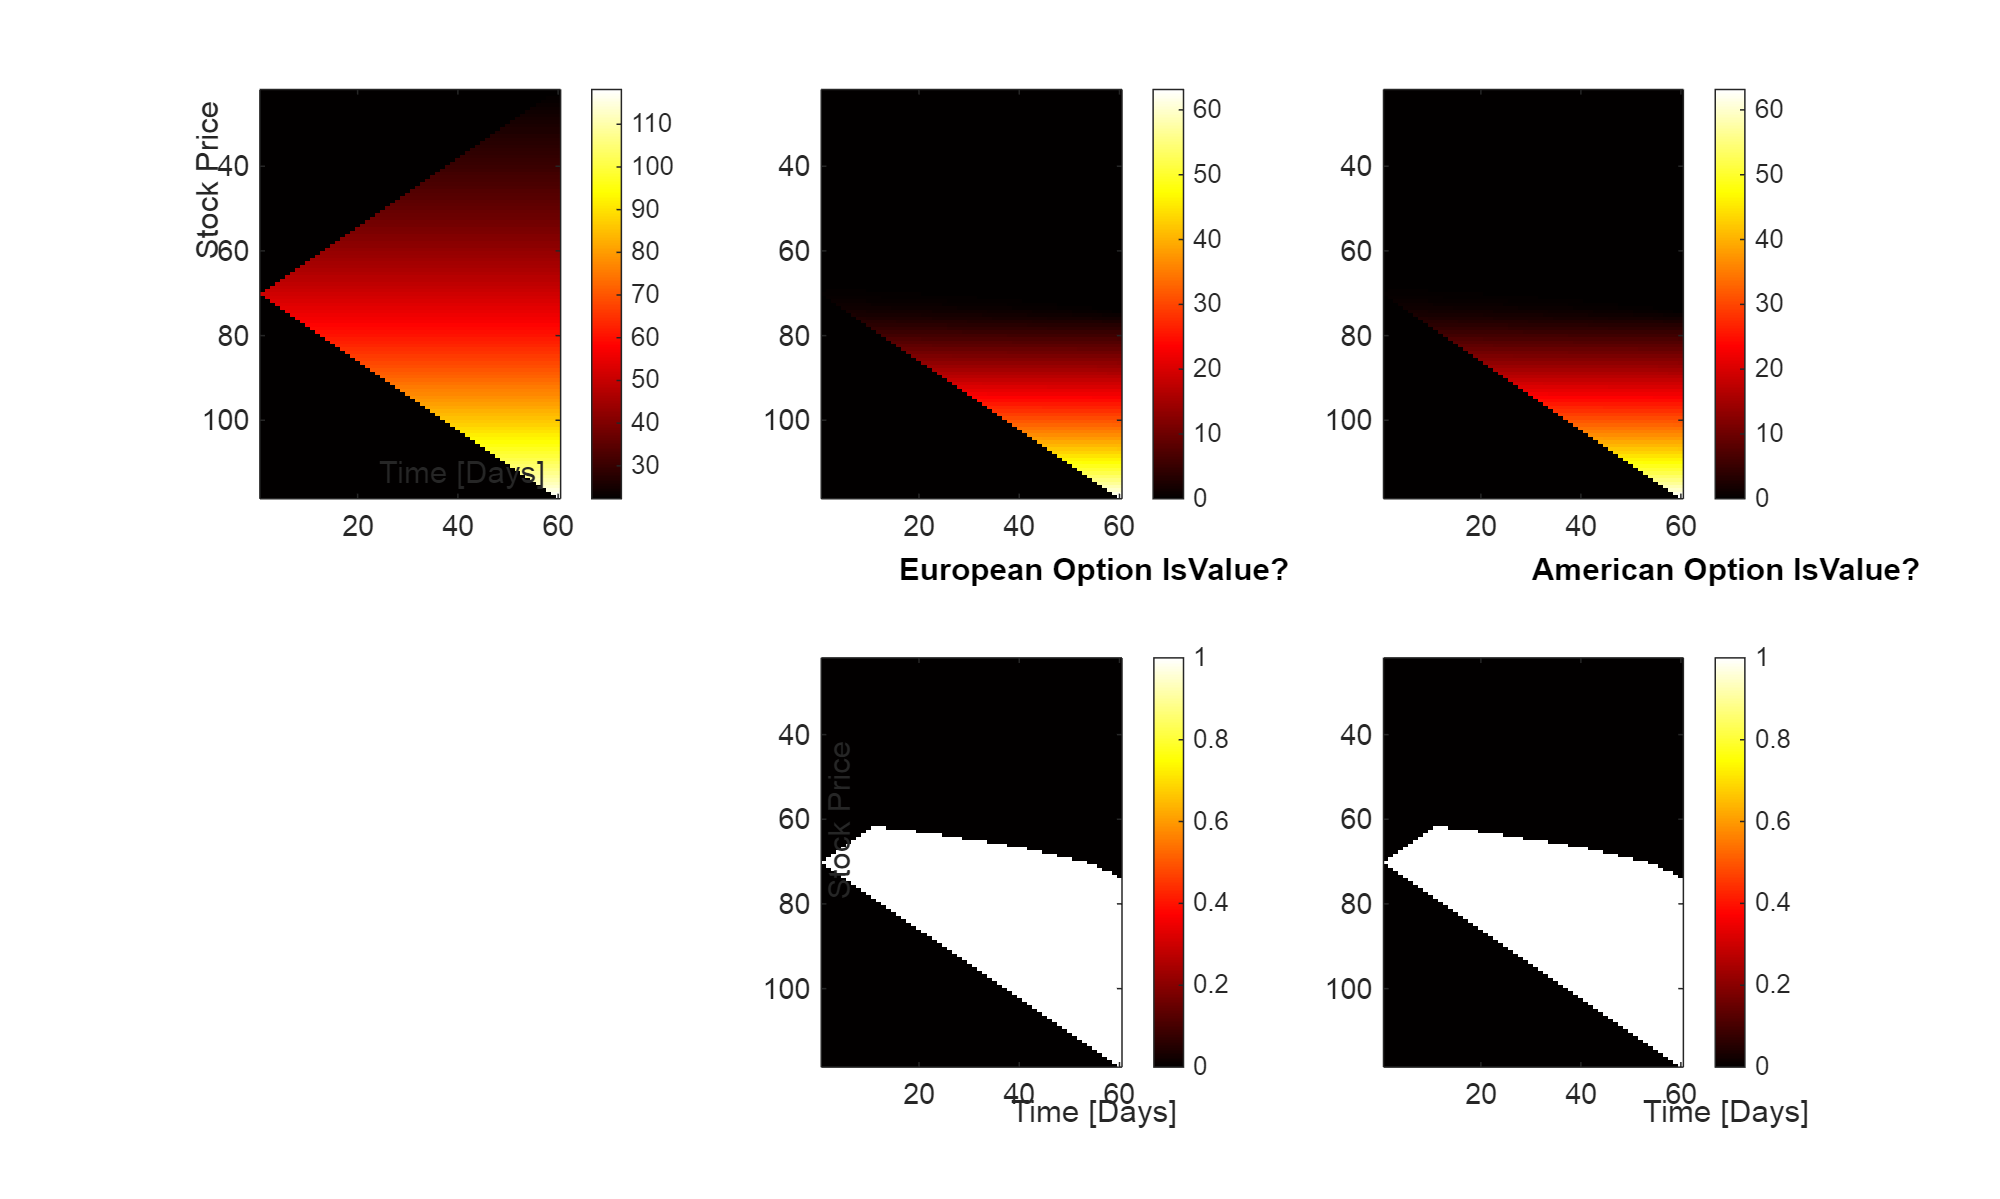


figure()
set(gcf, 'Position', [0,0,1000,600])
 
colormap(hot)
 
subplot(2,3,1)
imagesc(TAxis, SAxis, STriGrid)
colorbar
title('Stock Price')
ylabel('Stock Price')
xlabel('Time [Days]')
 
subplot(2,3,2)
imagesc(TAxis, SAxis, VEuro)
colorbar
title('European Option Price')
 
subplot(2,3,3)
nonzeroVAmer = zeros(size(VAmer));
nonzeroVAmer(VAmer > 0.001) = 1;
imagesc(TAxis, SAxis, VAmer)
colorbar
title('American Option Price')
 
 
subplot(2,3,5)
nonzeroVEuro = zeros(size(VEuro));
nonzeroVEuro(VEuro > 0.001) = 1;
imagesc(TAxis, SAxis, nonzeroVEuro)
colorbar
title('European Option IsValue?')
ylabel('Stock Price')
xlabel('Time [Days]')
 
subplot(2,3,6)
nonzeroVAmer = zeros(size(VAmer));
nonzeroVAmer(VAmer > 0.001) = 1;
imagesc(TAxis, SAxis, nonzeroVAmer)
colorbar
title('American Option IsValue?')
xlabel('Time [Days]')

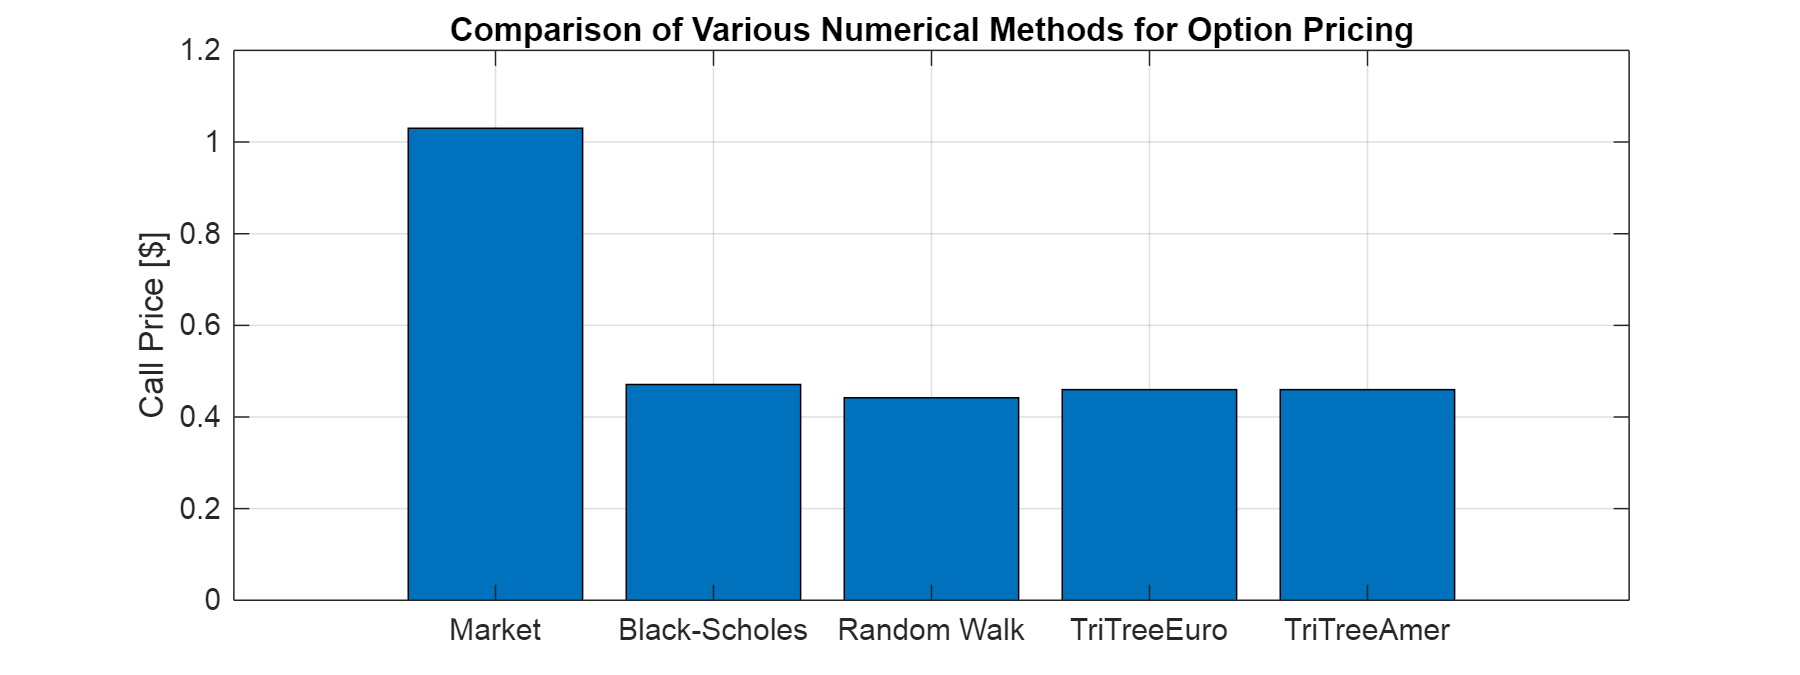


% Update on call option price by various methods
figure()
 
set(gcf,'Position',[0,0,800,300])
 
bar([C_MKT, C_BSM, C_RW, C_TRI_EURO, C_TRI_AMER])
title('Comparison of Various Numerical Methods for Option Pricing')
ylabel('Call Price [$]')
set(gca, 'XTickLabels', {'Market','Black-Scholes','Random Walk','TriTreeEuro','TriTreeAmer'})
 
box on
grid on

### 4. Application: Binary Option

Now let's assume we are sitting on a bespoke derivatives desk. A client calls and asks for a market on ...

Barrier Option has value $1,000,000 if stock at expiration above $55, zero otherwise. Epxires Dec 15, 2023, just like the calls above.

#### (1) Binary Option via Random Walk

% Calculate value of the Binary option
B_RW = zeros(size(S_RW));
B_RW(S_RW >= 55) = 1;
 
B_RW_Expiration = max(0, sign(S_RW(end,:)-55));
 
PriceExp = [0,1];
CountExp = hist(B_RW_Expiration, PriceExp);
 
ProbExp = CountExp / NTrials;
 
BinaryValueRW = PriceExp * ProbExp' % expected value of the option price

BinaryValueRW = 0.1900

function str = num2bank(value)
    % Converts a number to a bank-style string with commas and two decimals
    str = sprintf('%.2f', value);  % Format the number with 2 decimal places
    str = regexprep(str, '(\d)(?=(\d{3})+\.)', '$1,');  % Add commas
end
disp(num2bank(1e6 * BinaryValueRW))

190,000.00


#### (2) Binary Option via Trinomial Tree

% Determine the option Value
BinaryIntrinsic = zeros(size(STriGrid));
BinaryIntrinsic(STriGrid >= 55) = 1;
BinaryEuro = NaN(size(STriGrid));
 
% Backward Induction
for j = NSteps:-1:1
 
    I = (NSteps - j + 1):(NSteps + j - 1);
 
    for i = 1:length(I)
        
        if j == NSteps    
            % Option prices at maturity are just Intrinsic Values
            BinaryEuro(I(i), j) = BinaryIntrinsic(I(i),j);
        else
            % The Backward Induction Algorithm
            BinaryEuro(I(i), j) = exp(-bRwDays*dt) * (pu * BinaryEuro(I(i)+1, j+1) + ...
                                                      pm * BinaryEuro(I(i),   j+1) + ...
                                                      pd * BinaryEuro(I(i)-1, j+1) );
        end%if
    end%for i
end%for j
 
disp(BinaryEuro(NSteps,1))

    0.2127




disp(num2bank(1000000 * BinaryEuro(NSteps,1)))

212,742.80


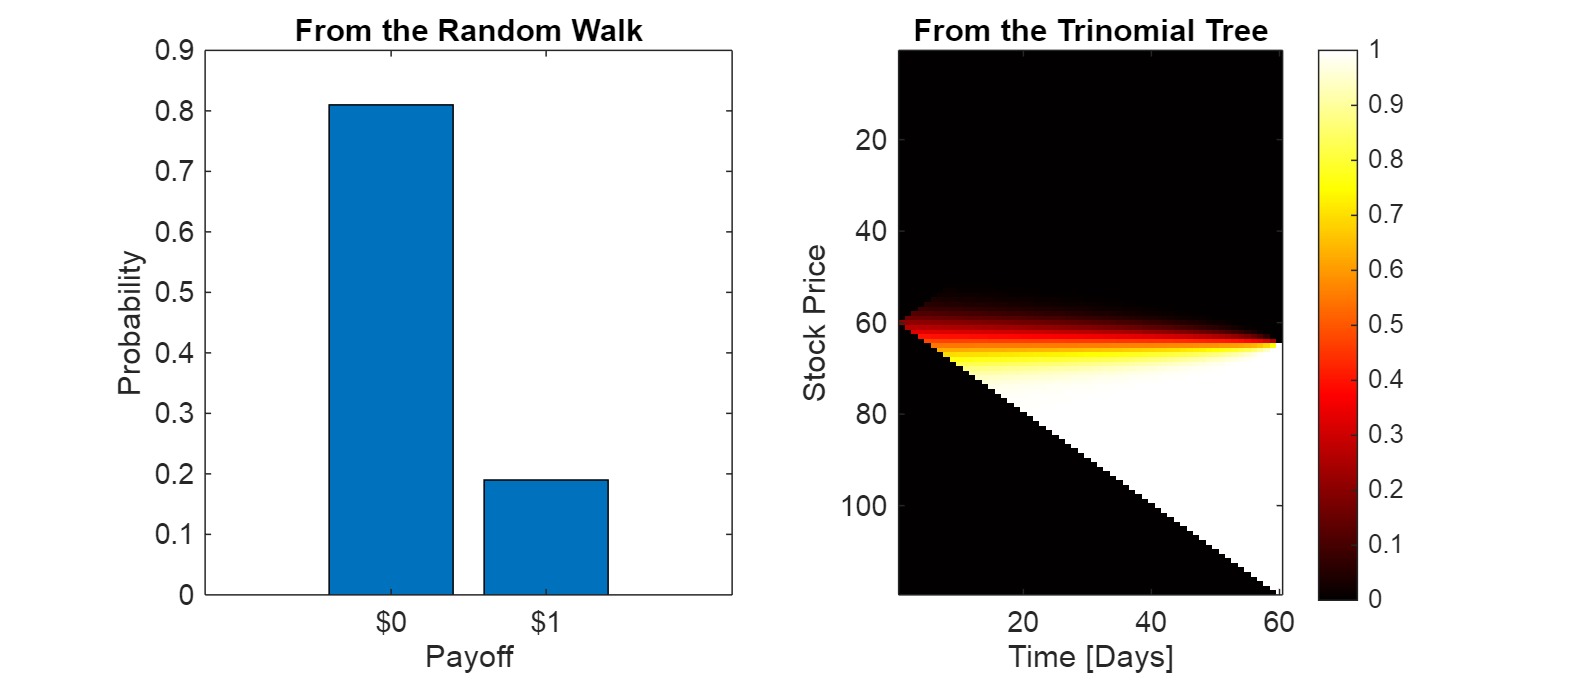


% Results and Graphs
figure()
set(gcf,'Position',[0,0,700,300])
 
subplot(1,2,1)
bar(ProbExp)
title('From the Random Walk')
ylabel('Probability')
xlabel('Payoff')
set(gca,'XTickLabels',{'$0','$1'})
 
subplot(1,2,2)
imagesc(BinaryEuro)
title('From the Trinomial Tree')
xlabel('Time [Days]')
ylabel('Stock Price')
colormap(hot)
colorbar

### 5. Application: Double Binary Option

Client calls back and asks for a market on:

Barrier Option has value $1,000,000 if stock at expiration above $55 and below $45, zero otherwise. Epxires Dec 15, 2023, just like the calls above.

#### (1) Double Binary Option via Random Walk

% Calculate value of the Binary option
B2_RW = zeros(size(S_RW));
B2_RW((S_RW >= 55) | (S_RW <= 45)) = 1;
 
B2_RW_Expiration = max(0, sign(S_RW(end,:) - 55)) + max(0, sign(45 - S_RW(end,:)));
 
PriceExp = [0,1];
CountExp = hist(B2_RW_Expiration, PriceExp);
 
ProbExp = CountExp / NTrials;
 
DblBinaryValueRW = PriceExp * ProbExp' % expected value of the option price

DblBinaryValueRW = 0.2310


disp(num2bank(1e6 * DblBinaryValueRW))

231,000.00


#### (2) Double Binary Option via Trinomial Tree

% Determine the option Value
DblBinaryIntrinsic = zeros(size(STriGrid));
DblBinaryIntrinsic((STriGrid >= 55) | (STriGrid <= 45)) = 1;
DblBinaryEuro = NaN(size(STriGrid));
 
% Backward Induction
for j = NSteps:-1:1
 
    I = (NSteps - j + 1):(NSteps + j - 1);
 
    for i = 1:length(I)
 
        if j == NSteps    
            % Option prices at maturity are just Intrinsic Values
            DblBinaryEuro(I(i), j) = DblBinaryIntrinsic(I(i),j);
        else
            % The Backward Induction Algorithm
            DblBinaryEuro(I(i), j) = exp(-bRwDays*dt) * (pu * DblBinaryEuro(I(i)+1, j+1) + ...
                                                         pm * DblBinaryEuro(I(i),   j+1) + ...
                                                         pd * DblBinaryEuro(I(i)-1, j+1) );
        end%if
    end%for i
end%for j
 
DblBinaryEuro(NSteps,1)

ans = 0.2495


disp(num2bank(1000000 * DblBinaryEuro(NSteps,1)))

249,491.28


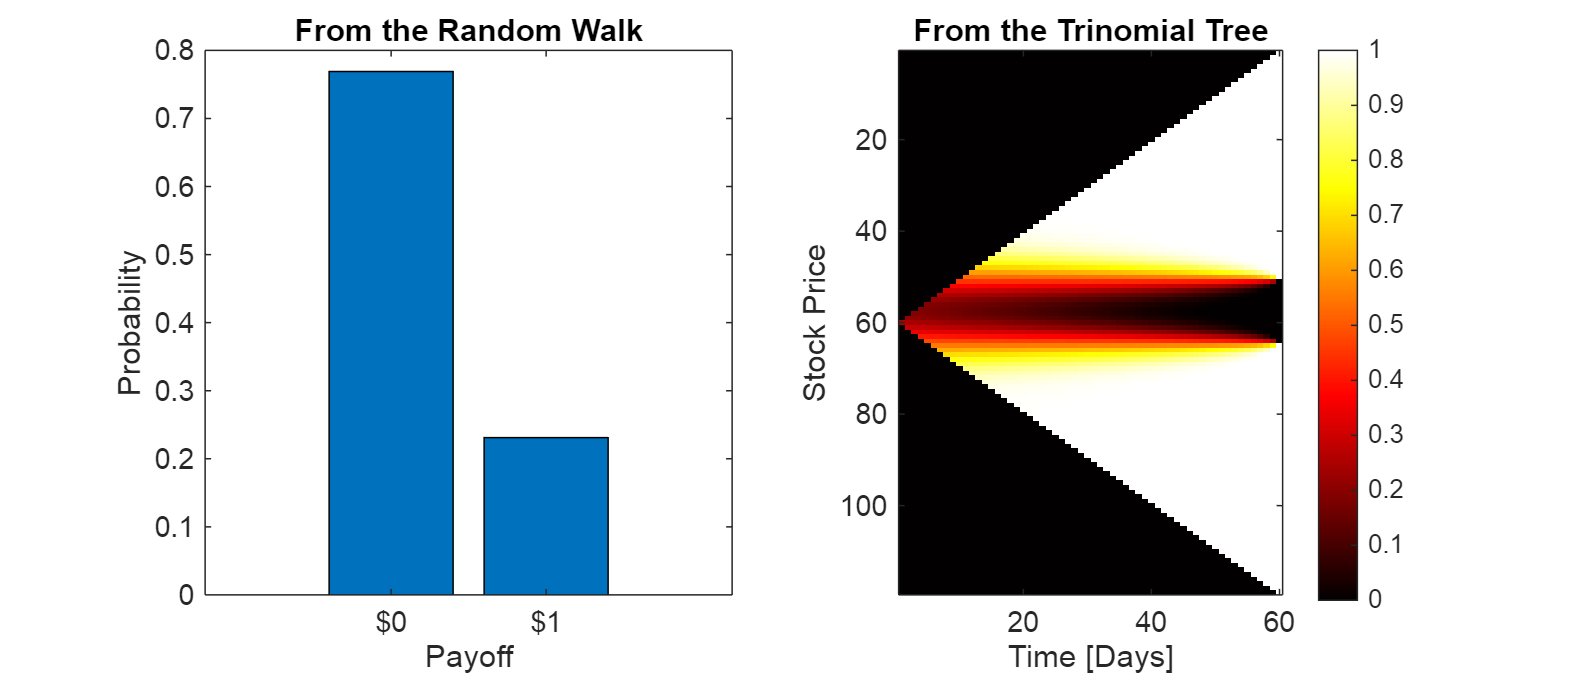


% Results and Graphs
figure()
set(gcf,'Position',[0,0,700,300])
 
subplot(1,2,1)
bar(ProbExp)
title('From the Random Walk')
ylabel('Probability')
xlabel('Payoff')
set(gca,'XTickLabels',{'$0','$1'})
 
subplot(1,2,2)
imagesc(DblBinaryEuro)
title('From the Trinomial Tree')
xlabel('Time [Days]')
ylabel('Stock Price')
colormap(hot)
colorbar

### 6. Application: One-Touch Double Binary Option

Client calls back and asks for a market on:

Barrier Option has value $1,000,000 if stock hits $55 or $45 at any time before expiration, zero otherwise. Epxires Dec 15, 2023, just like the calls above.

#### (1) Double Binary Option via Random Walk

% Calculate value of the Binary option
B3_RW = zeros(size(S_RW));
for j=1:size(S_RW,2)
    for i=1:size(S_RW,1)
        if S_RW(i,j) >= 55 | S_RW(i,j) <= 45
            B3_RW(i:end,j) = 1;
            break
        end
    end
end
 
B3_RW_Expiration = B3_RW(end,:);
 
PriceExp = [0,1];
CountExp = hist(B3_RW_Expiration, PriceExp);
 
ProbExp = CountExp / NTrials;
 
B3ValueRW = PriceExp * ProbExp' % expected value of the option price

B3ValueRW = 0.4150


disp(num2bank(1e6 * B3ValueRW))

415,000.00


#### (2) Double Binary Option via Trinomial Tree

% Determine the option Value
DblBinary3Intrinsic = zeros(size(STriGrid));
DblBinary3Intrinsic((STriGrid >= 55) | (STriGrid <= 45)) = 1;
DblBinary3Amer = NaN(size(STriGrid));
DblBinary3Euro = NaN(size(STriGrid));
 
 
% Backward Induction
for j = NSteps:-1:1
 
    I = (NSteps - j + 1):(NSteps + j - 1);
 
    for i = 1:length(I)
 
        IntrinsicValue = DblBinary3Intrinsic(I(i),j);
 
        if j == NSteps    
            % Option prices at maturity are just Intrinsic Values
            DblBinary3Euro(I(i), j) = IntrinsicValue; %DblBinary3Intrinsic(I(i),j);
            DblBinary3Amer(I(i), j) = IntrinsicValue; %DblBinary3Intrinsic(I(i),j);
        else
            % The Backward Induction Algorithm
            DblBinary3Euro(I(i), j) = exp(-bRwDays*dt) * (pu * DblBinary3Euro(I(i)+1, j+1) + ...
                                                          pm * DblBinary3Euro(I(i),   j+1) + ...
                                                          pd * DblBinary3Euro(I(i)-1, j+1) );
 
            % The Backward Induction Algorithm ... American
            DblBinary3Amer(I(i), j) = max(IntrinsicValue, exp(-bRwDays*dt) * ...
                                                             (pu * DblBinary3Amer(I(i)+1, j+1) + ...
                                                              pm * DblBinary3Amer(I(i),   j+1) + ...
                                                              pd * DblBinary3Amer(I(i)-1, j+1))); ...
 
        end%if
    end%for i
end%for j
 
 
 
DblBinary3Euro(NSteps,1)

ans = 0.2495


DblBinary3Amer(NSteps,1)

ans = 0.4317


disp(num2bank(1000000 * DblBinary3Amer(NSteps,1)))

431,726.37


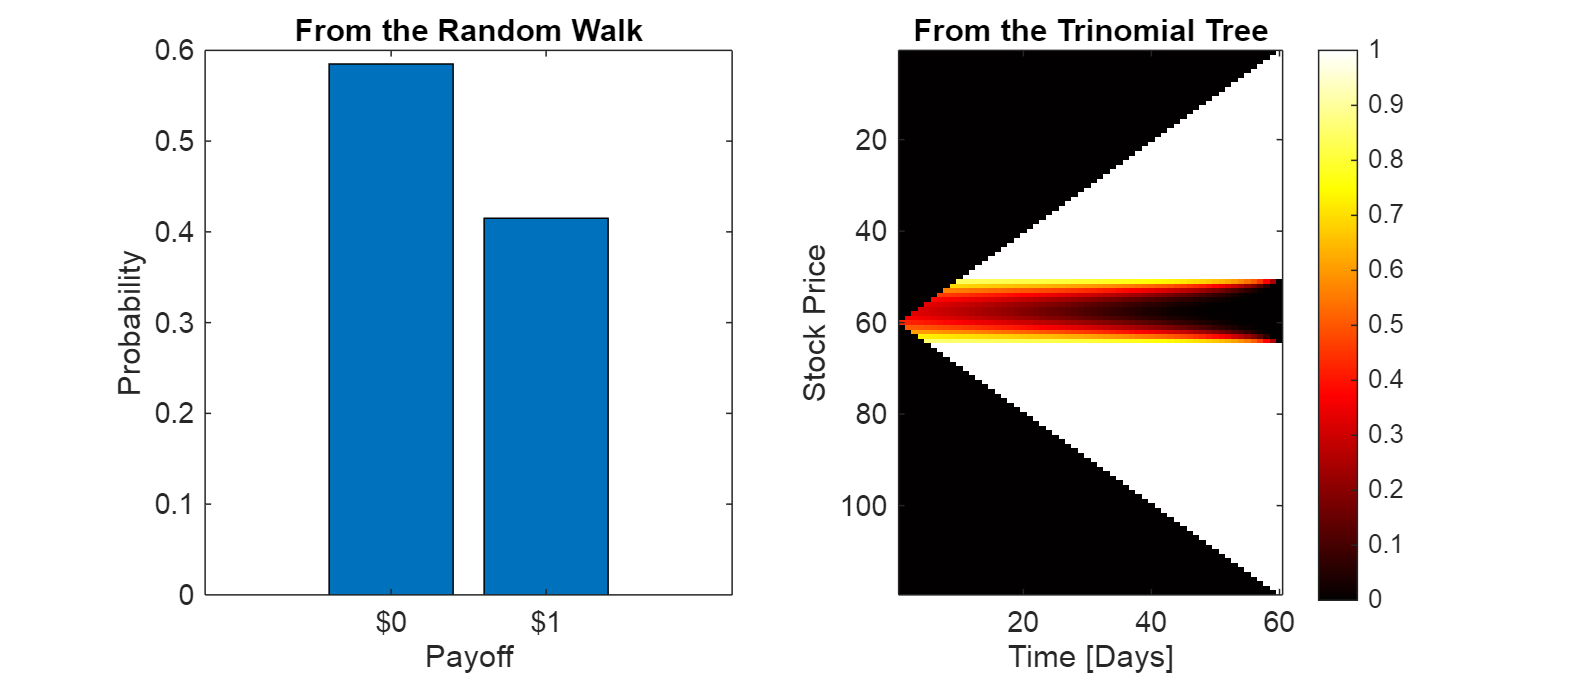


% Results and Graphs
figure()
set(gcf,'Position',[0,0,700,300])
 
subplot(1,2,1)
bar(ProbExp)
title('From the Random Walk')
ylabel('Probability')
xlabel('Payoff')
set(gca,'XTickLabels',{'$0','$1'})
 
subplot(1,2,2)
imagesc(DblBinary3Amer)
title('From the Trinomial Tree')
xlabel('Time [Days]')
ylabel('Stock Price')
colormap(hot)
colorbar